clear all
close all
clc

%Log data
AT_R = [5/43,10/43,20/43,31/43,41/43];
HT_R = 1 - AT_R;

AT_S = [2/41,9/41,18/41,29/41,30/41];
HT_S = 1 - AT_S;

Price = [30,18,15,12,7.5];

ColorCode = ["#0072BD",	"#4DBEEE",	"#D95319",	"#EDB120"]

ColorCode = 1×4 string array
    "#0072BD"    "#4DBEEE"    "#D95319"    "#EDB120"


legend_Price = ["AT-Rainy","HT-Rainy","AT-Sunny","HT-Sunny"]

legend_Price = 1×4 string array
    "AT-Rainy"    "HT-Rainy"    "AT-Sunny"    "HT-Sunny"



PricePlot=[AT_R;HT_R;AT_S;HT_S];

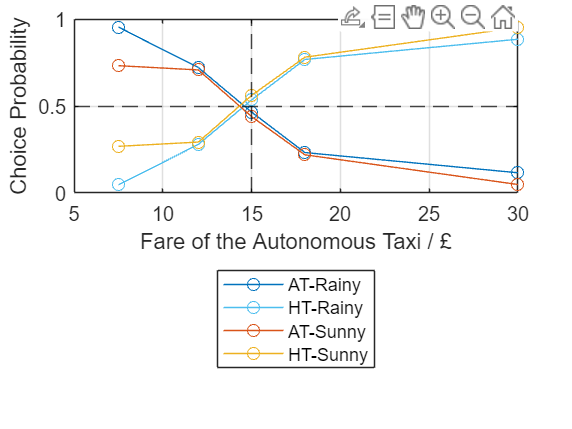

%Plot
for i = 1:4
    plot(Price,PricePlot(i,:),'o-','DisplayName',legend_Price(i),color=ColorCode(i))
    hold on
end

xlabel('Fare of the Autonomous Taxi / £')
ylabel('Choice Probability')
legend(Location="southoutside")

xline(15,'k--','HandleVisibility','off')
yline(0.5,'k--','HandleVisibility','off')
grid on
hold off

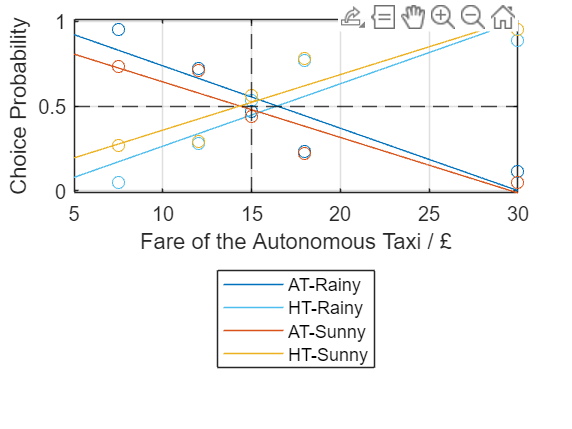

%Linear regression
dataRange = [5:0.01:30];
for j = 1:4
    fit = polyfit(Price,PricePlot(j,:),1);
    plot(dataRange,polyval(fit,dataRange),'DisplayName',legend_Price(j),color=ColorCode(j))
    hold on
    scatter(Price,PricePlot(j,:),'o','HandleVisibility','off','MarkerEdgeColor',ColorCode(j))
end

xlabel('Fare of the Autonomous Taxi / £')
ylabel('Choice Probability')
legend(Location="southoutside")

xline(15,'k--','HandleVisibility','off')
yline(0.5,'k--','HandleVisibility','off')
grid on
hold off